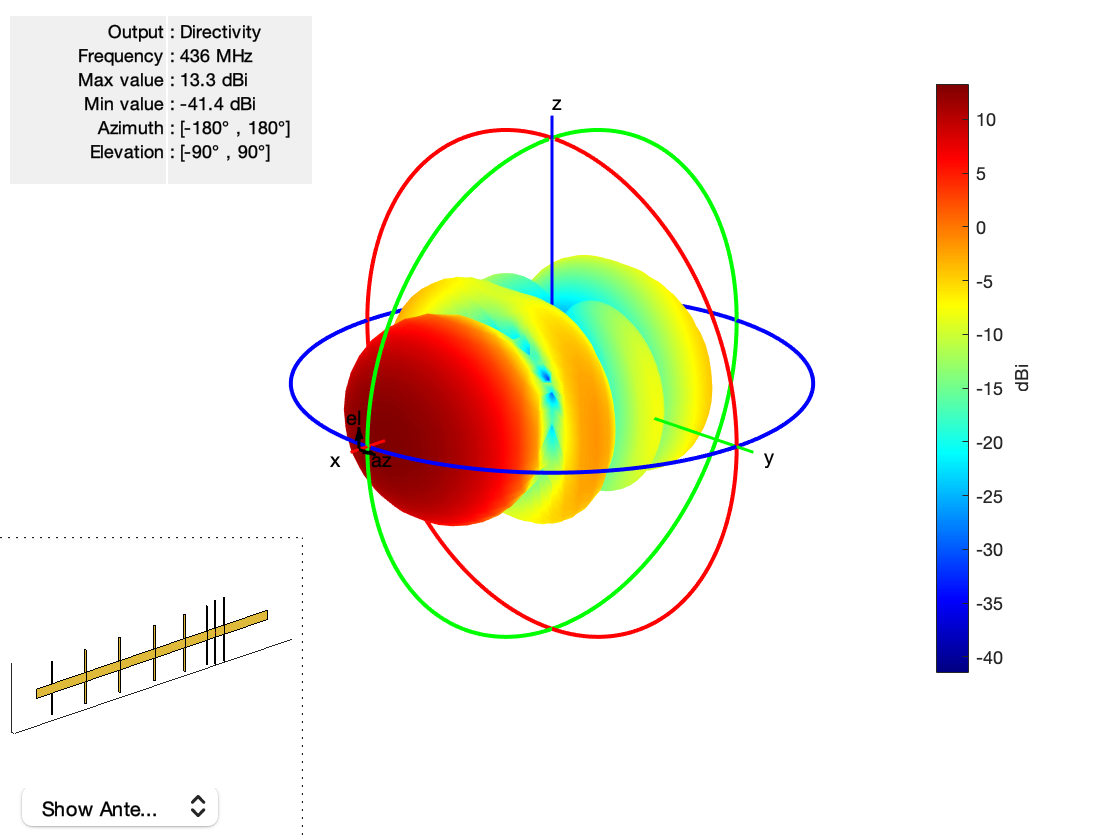

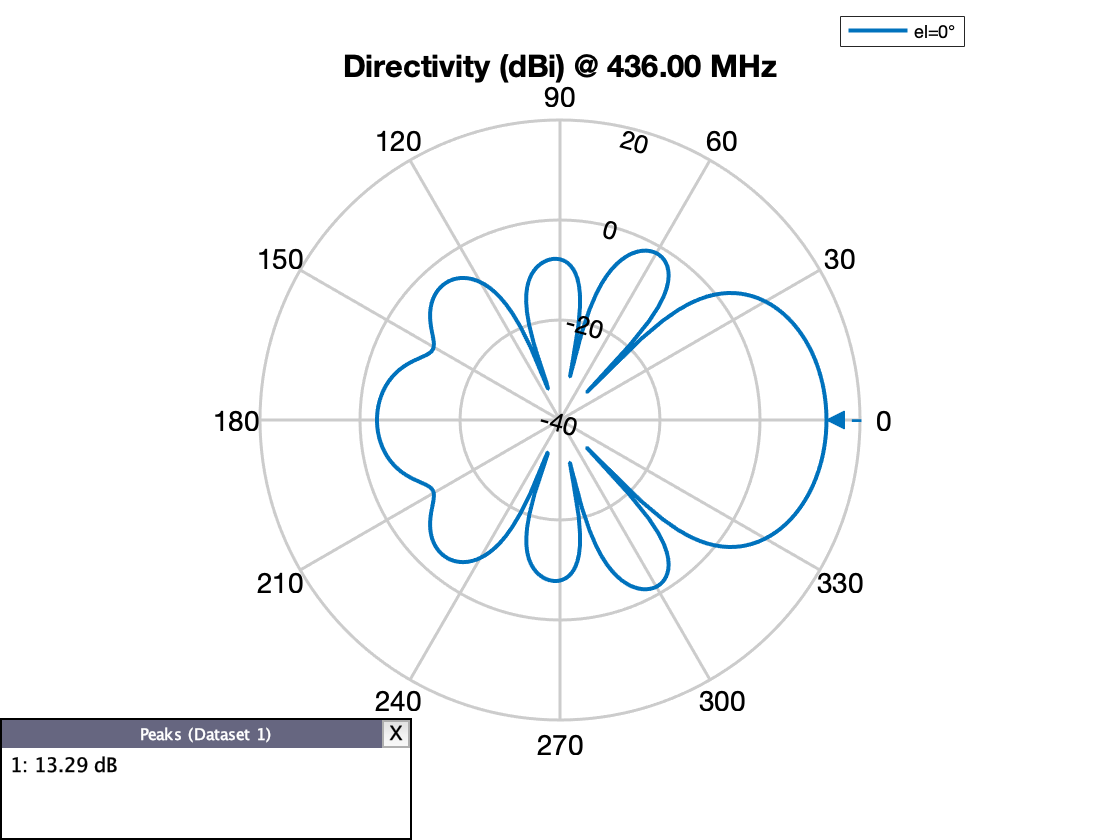

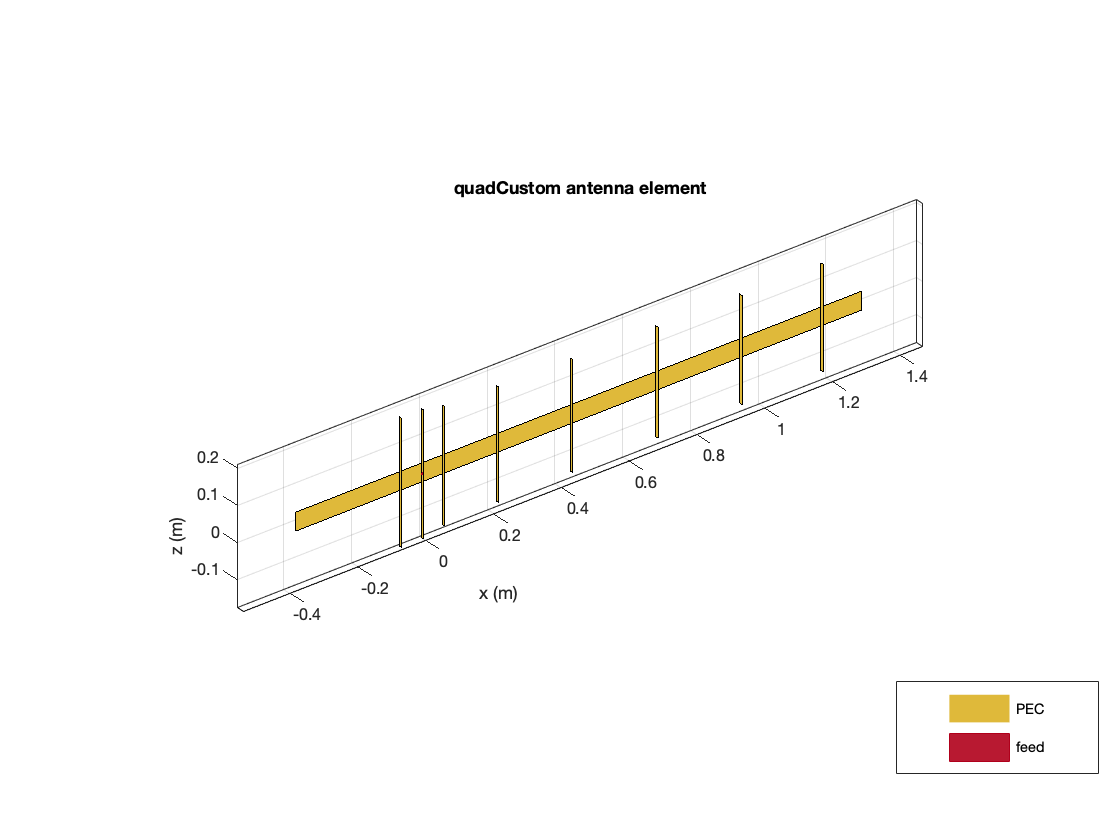

% This models the 436 CP16 antenna .
% Parameter : Datasheet / Model
% Gain : 13.3 dBic / 13.3 dBi
% Front -to - back : 15 dB / 16.6 dB
 % HPBW : 42.0 / 48.0
d1 = dipole ('Length' ,12.625*.0254 , 'Width' , cylinder2strip((3/32)*.0254) ,...
'Tilt' ,90,'TiltAxis' ,[0 1 0]);
d2 = dipole ('Length' ,12.250*.0254 , 'Width', cylinder2strip((3/32)*.0254),...
 'Tilt' ,90,'TiltAxis' ,[0 1 0]);
d3 = dipole ('Length',11.937*.0254 , 'Width', cylinder2strip((3/32)*.0254),...
'Tilt' ,90,'TiltAxis' ,[0 1 0]);
d4 = dipole ('Length' ,11.750*.0254 , 'Width', cylinder2strip((3/32)*.0254),...
 'Tilt' ,90,'TiltAxis' ,[0 1 0]);
d5 = dipole ('Length' ,11.531*.0254 , 'Width', cylinder2strip((3/32)*.0254),...
'Tilt' ,90,'TiltAxis' ,[0 1 0]);
d6 = dipole ('Length',11.375*.0254 , 'Width', cylinder2strip((3/32)*.0254),...
'Tilt',90,'TiltAxis' ,[0 1 0]);
r = dipole ('Length' ,13.687*.0254 , 'Width', cylinder2strip((3/32)*.0254),...
'Tilt' ,90,'TiltAxis' ,[0 1 0]);
dip=dipole('Length',13.625*0.0254,'Width',cylinder2strip((3/32)*0.0254),...
'Tilt',90,'TiltAxis' ,[0 1 0]) ;
uhf = quadCustom('Exciter',dip,...
'Director', {d1 d2 d3 d4 d5 d6 } ,...
'DirectorSpacing', [(17 -14.562) (23.313 -17) (31.875 -23.313)...
(41.813 -31.875) (51.563 -41.813) (61 -51.563)].*0.0254 ,...
'Reflector' ,{r} ,...
'ReflectorSpacing', 2.562*0.0254 ,...
'BoomLength', 65.75*0.0254 ,...
'BoomWidth', cylinder2strip((1/2)*0.0254) ,...
'BoomOffset' ,[0 0.005 (65.75/2 -14.562)*0.0254] ,...
'Tilt' ,90 ,...
'TiltAxis' ,[0 1 0]);

coords =     3.2176    0.6260    2.6644   -5.9518   -5.2621    0.9792    2.7068   -2.0973    7.7062    5.6884   -1.9796   -1.1480   -6.0702   -4.3810    1.3278   -3.3529   -3.7555    7.7226   -2.4980   -6.2757
    2.6614    3.1697   -5.1499    7.9853   -7.4784    6.1099   -4.9531   -0.6284   -5.4975    2.3162   -4.9452   -0.2876    1.4321   -1.8461   -3.9711    1.8735    5.1900    3.6840    1.3451    6.5009


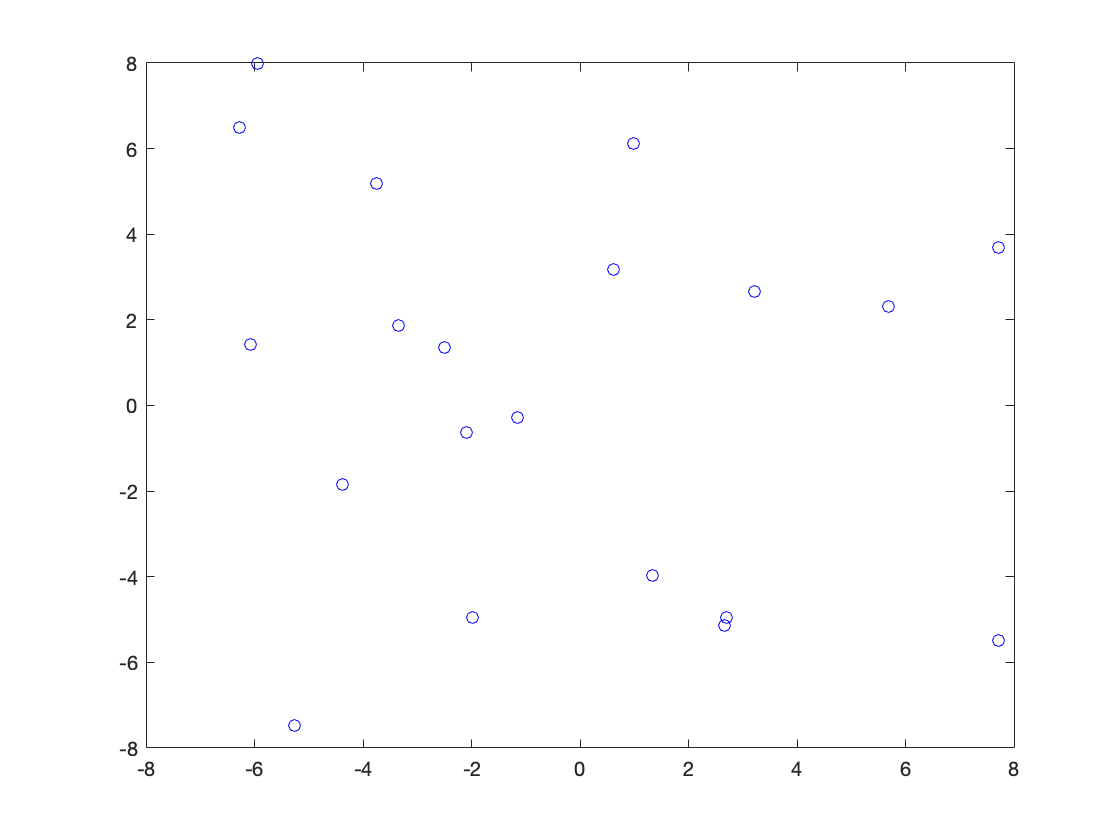

x =     6.1049
   12.7232
    7.8362
   10.3410
    2.6018
    7.9738
    4.0815
   11.1852
   15.3487
    3.8964


y =    12.2483
    2.9900
    7.1294
   11.3498
    1.9040
   15.3559
    8.0953
   14.2545
    8.7554
   14.8682


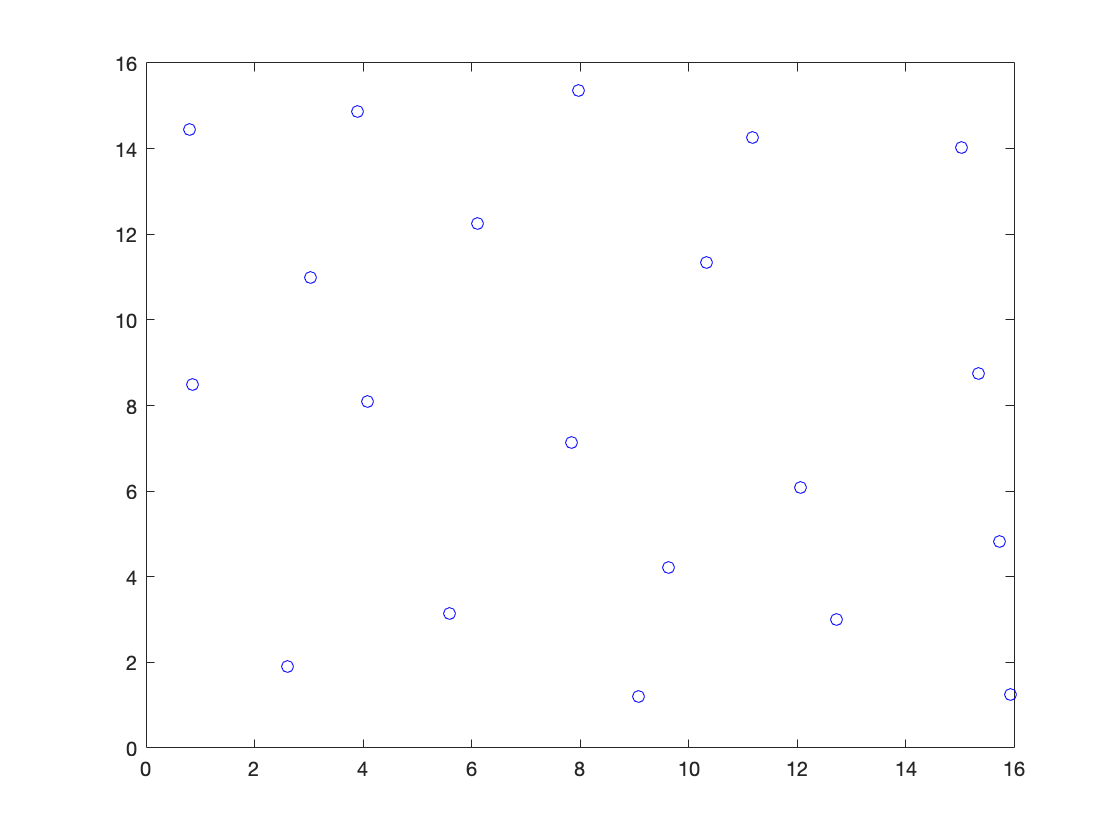

elempos =     6.1049   12.7232    7.8362   10.3410    2.6018    7.9738    4.0815   11.1852   15.3487    3.8964    5.5997   12.0597    9.0851    0.8632    9.6317   15.9382    0.7945    3.0233   15.0240   15.7288
   12.2483    2.9900    7.1294   11.3498    1.9040   15.3559    8.0953   14.2545    8.7554   14.8682    3.1455    6.0871    1.2137    8.4928    4.2075    1.2508   14.4435   10.9884   14.0151    4.8233
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


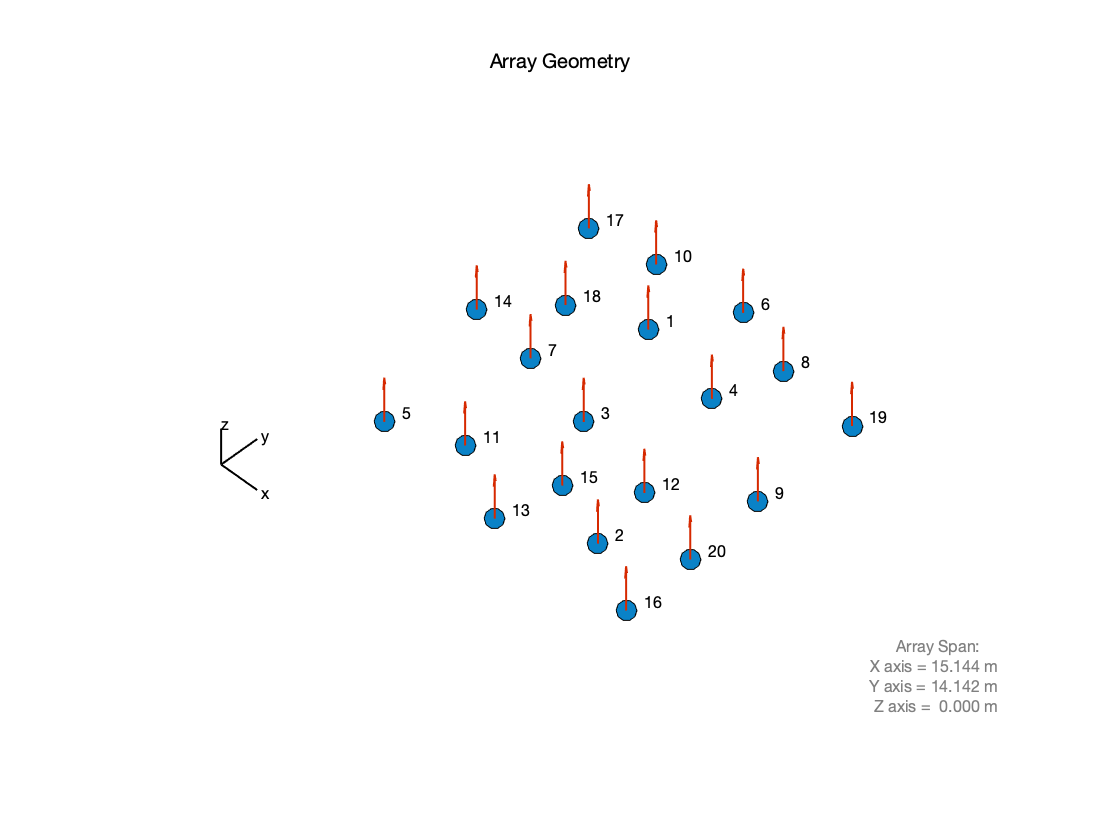

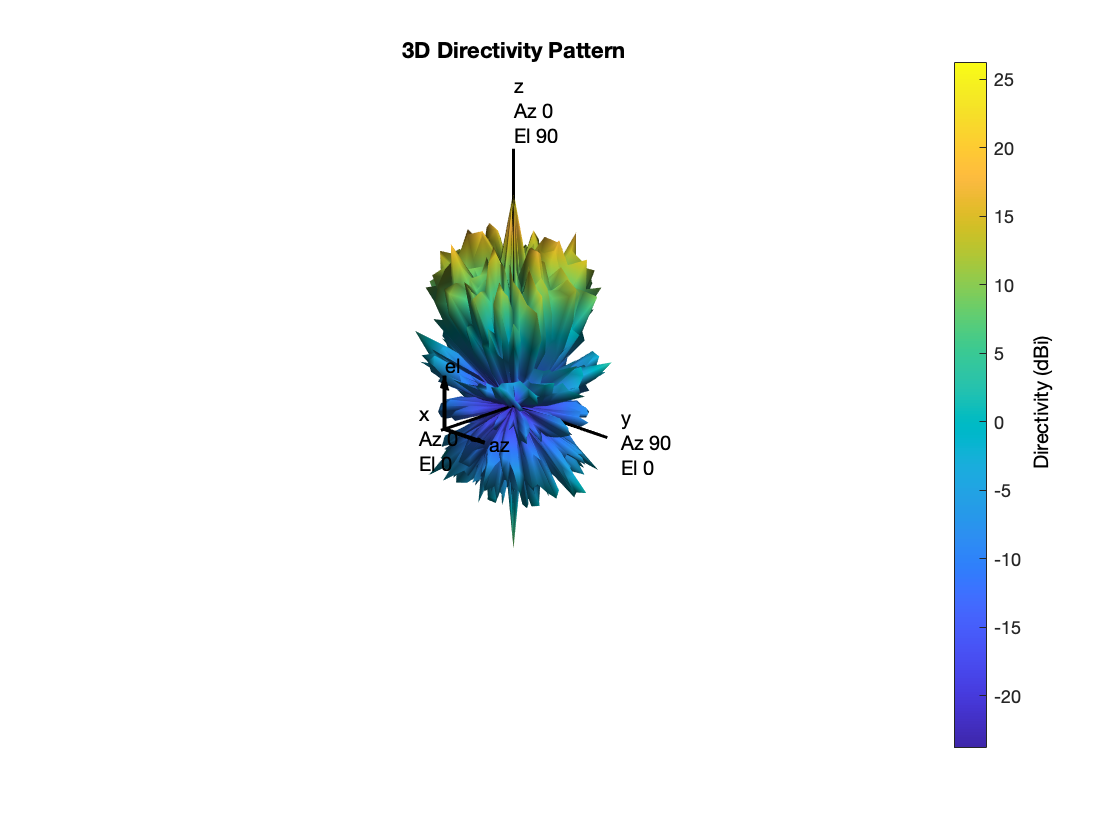

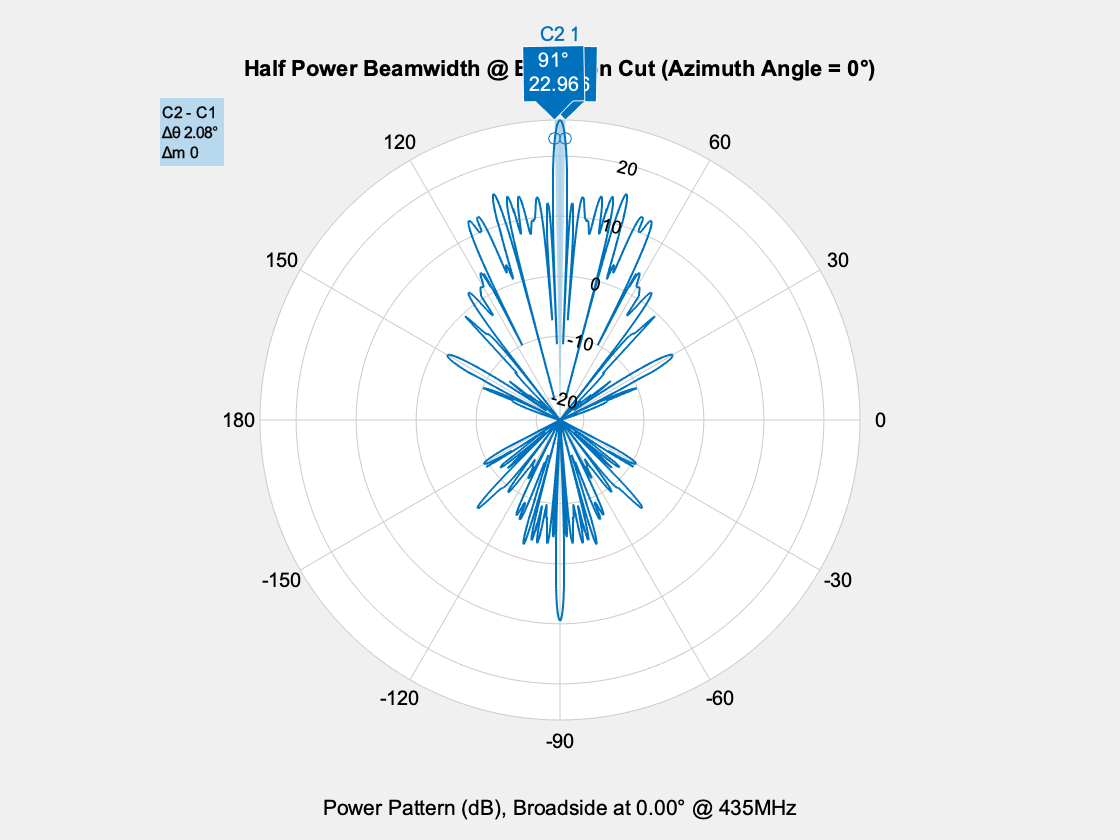

ans = 2.0800

b = 2.0800

a =    88.9600   91.0400


pat =     9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445    9.6445
    9.6237    9.6250    9.6263    9.6274    9.6281    9.6282    9.6277    9.6267    9.6255    9.6241    9.6229    9.6219    9.6213    9.6210    9.6210    9.6212    9.6218    9.6226    9.6237    9.6250    9.6263    9.6274    9.6281    9.6282    9.6277    9.6267    9.6255    9.6241    9.6229    9.6219    9.6213    9.6210    9.6210    9.6212    9.6218    9.6226    9.6237
    9.6029    9.6054    9.6080    9.6102    9.6116    9.6119    9.6109    9.6089    9.6064    9.6037    9.6012    9.5993    9.5980    9.5974    9.5973    9.5979    9.5990    9.6007    9.6029    9.6054    9.6080    9.6102    9.6116    9.6119    9.6109  

az =   -180  -170  -160  -150  -140  -130  -120  -110  -100   -90   -80   -70   -60   -50   -40   -30   -20   -10     0    10    20    30    40    50    60    70    80    90   100   110   120   130   140   150   160   170   180


el =   -90.0000  -89.9900  -89.9800  -89.9700  -89.9600  -89.9500  -89.9400  -89.9300  -89.9200  -89.9100  -89.9000  -89.8900  -89.8800  -89.8700  -89.8600  -89.8500  -89.8400  -89.8300  -89.8200  -89.8100  -89.8000  -89.7900  -89.7800  -89.7700  -89.7600  -89.7500  -89.7400  -89.7300  -89.7200  -89.7100  -89.7000  -89.6900  -89.6800  -89.6700  -89.6600  -89.6500  -89.6400  -89.6300  -89.6200  -89.6100  -89.6000  -89.5900  -89.5800  -89.5700  -89.5600  -89.5500  -89.5400  -89.5300  -89.5200  -89.5100


L = struct with fields:
     mainLobe: [1×1 struct]
     backLobe: [1×1 struct]
    sideLobes: [1×1 struct]
           FB: 67.2936
          SLL: 11.4306
         HPBW: 2.1199
         FNBW: 16.0191
        FBIdx: [18001 9.0005e+03]
       SLLIdx: [18001 16401]
      HPBWIdx: [17896 1]
      HPBWAng: [357.8801 0]
      FNBWIdx: [17601 401]


MainLobe = struct with fields:
        index: 18001
    magnitude: 26.2029
        angle: 359.9800
       extent: [17601 401]


SideLobe = struct with fields:
        index: 16401
    magnitude: 14.7722
        angle: 327.9818
       extent: [23×2 double]


BackLobe = struct with fields:
    magnitude: -41.0907
        angle: 179.9800
       extent: [7601 10201]
        index: 9.0005e+03


MLR = 1.7738

fc =435e6; % For UHF = 435e6 , f o r VHF = 146 e6
c = physconst ('LightSpeed');
ant = uhf;
wavelength = c/fc;